# Analyzing Deforestation in the Amazon Rainforest

This script calculates the change in the deforested area of a region in the Jamanxim National Forest in Brazil. Five images of this region taken every four years are used - 2000, 2004, 2008, 2012, and 2016.

These images are courtesy of the [NASA Earth Observatory](https://earthobservatory.nasa.gov/images/145988/tracking-amazon-deforestation-from-above).

See the *Getting Started with Image Processing in MATLAB* video for details.

Copyright 2021 The MathWorks, Inc.

Display the image from 2000.

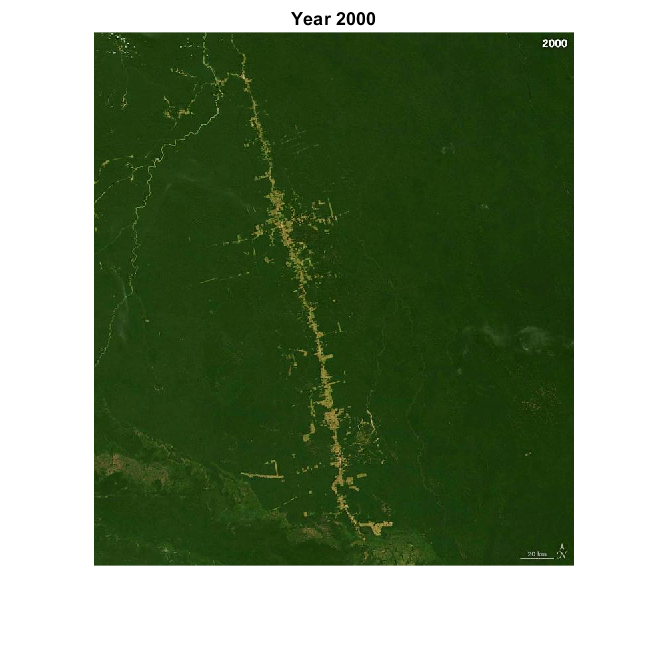

% This is imported interactively in the video.
year2000 = imread("year2000.jpg");
imshow(year2000)
title("Year 2000")

Compare to 2016.

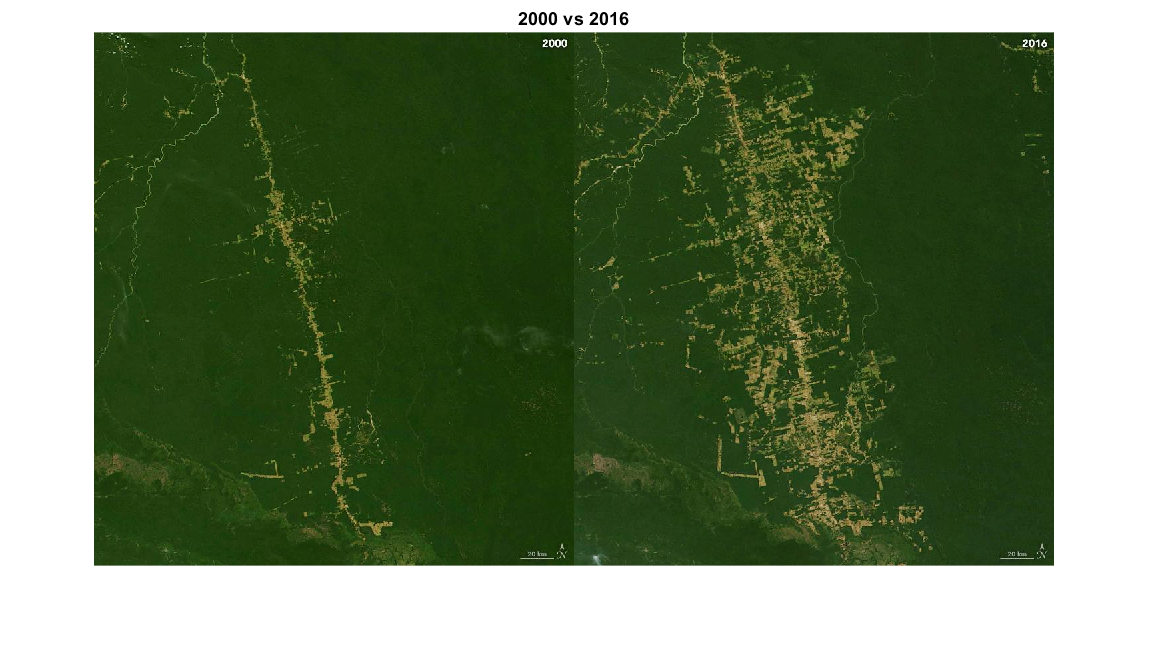

year2016 = imread("year2016.jpg");
imshowpair(year2000,year2016,"montage")
title("2000 vs 2016")

Convert to grayscale.

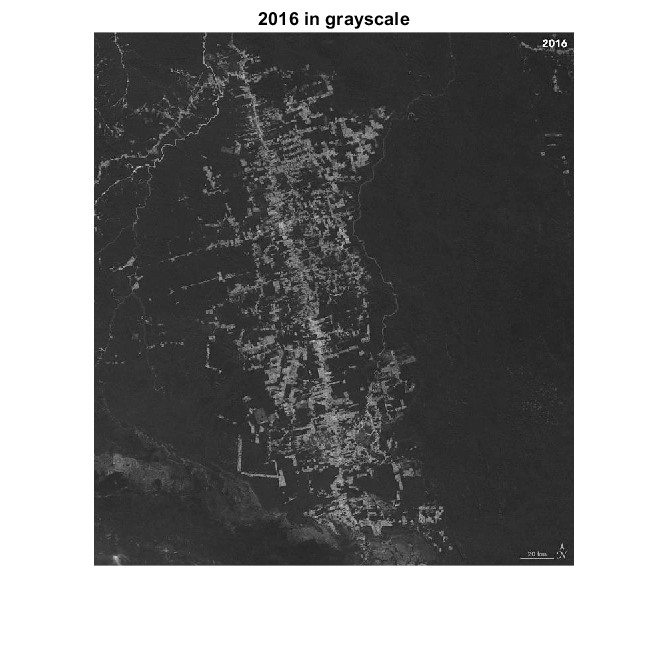

gray2016 = im2gray(year2016);
imshow(gray2016)
title("2016 in grayscale")

Display histogram.

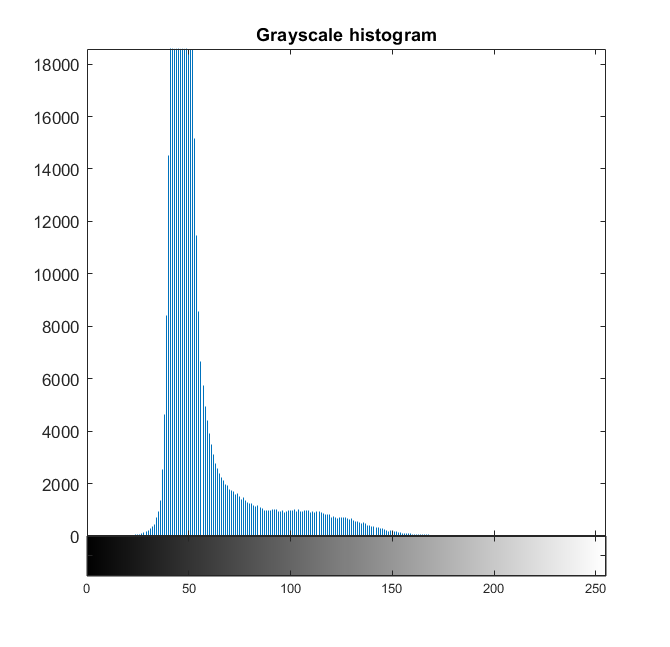

imhist(gray2016)
title("Grayscale histogram")

Adjust contrast.

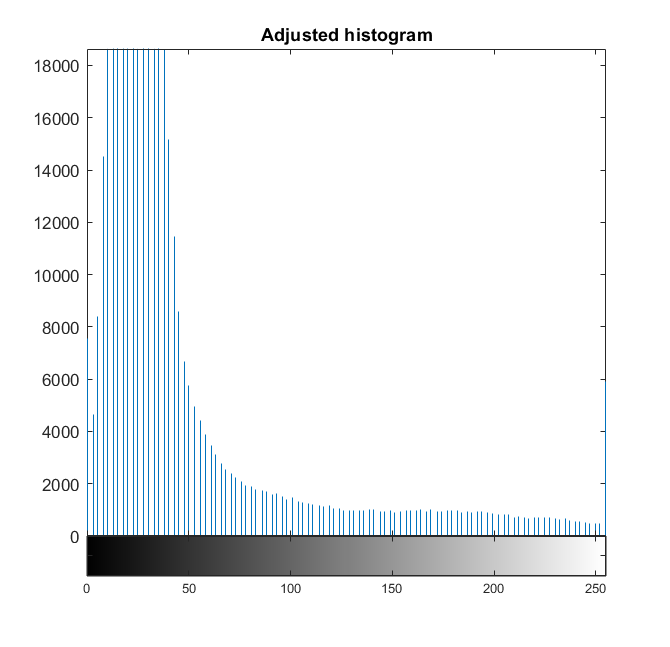

adj2016 = imadjust(gray2016);
imhist(adj2016)
title("Adjusted histogram")

Compare and contrast.

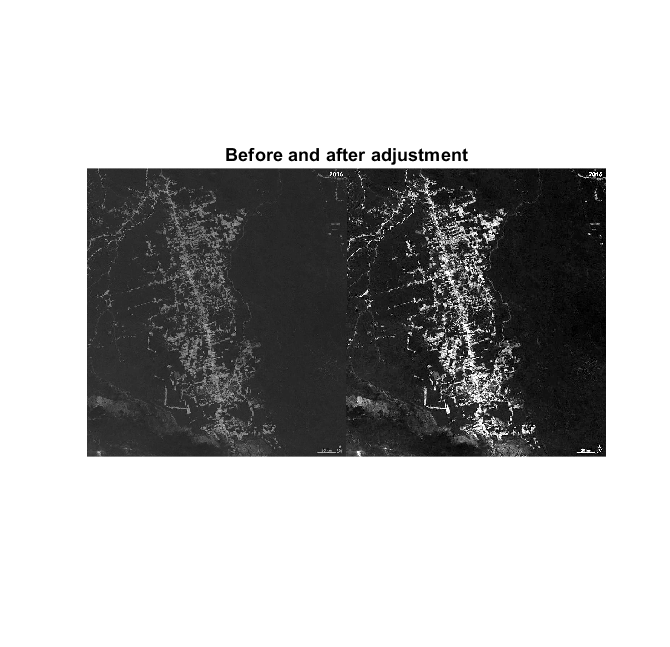

imshowpair(gray2016,adj2016,"montage")
title("Before and after adjustment")

Import the image from 2004.

year2004 = imread("year2004.jpg");
gray2004 = im2gray(year2004);
adj2004 = imadjust(gray2004);

Try color thresholding on 2004.

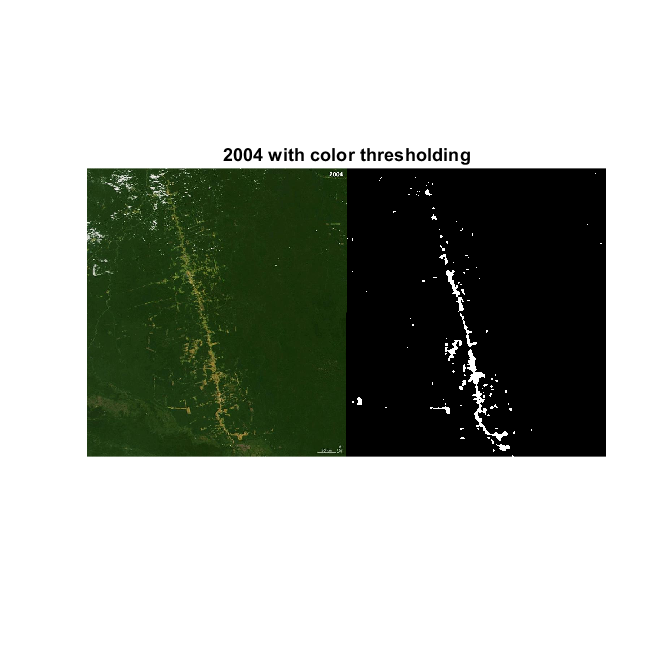

bw2004 = createMask(year2004);
imshowpair(year2004,bw2004,"montage")
title("2004 with color thresholding")

Calculate the area in pixels.

props = regionprops("table",bw2004,"Area")

props = 116×1 table
    Area
    ____
      6 
     12 
     32 
      9 
     24 
      2 
    244 
      2 
      1 
      3 
      6 
      2 
      3 
      9 
      1 
      2 

areaPixels = sum(props.Area)

areaPixels = 12041

Convert pixels to square kilometers.

px2km = (51/20)^2

px2km = 6.5025

areaKmSq = round(areaPixels*px2km)

areaKmSq = 78297

Plot area vs year as a bar plot.

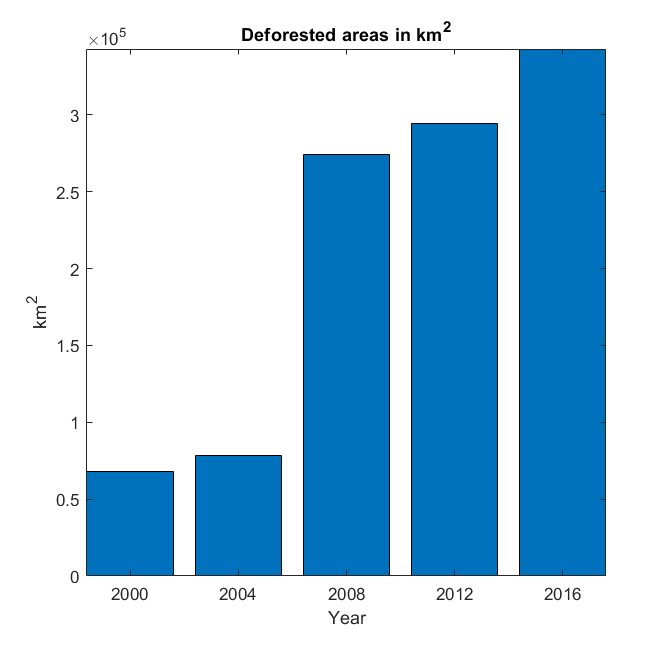

% Results generated by the Image Batch Processor App.
load allresults.mat
years = 2000:4:2016;
areas = allresults.areaKmSq;
bar(years,areas)
title("Deforested areas in km^{2}")
xlabel("Year")
ylabel("km^{2}")
axis tight

Display all segmented images.

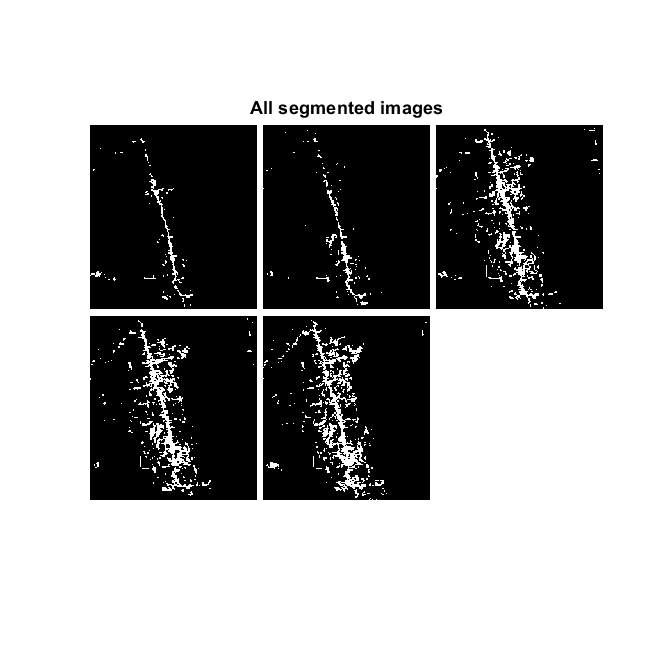

segmentedImages = allresults.BW;
montage(segmentedImages,...
    "BackgroundColor","White",...
    "BorderSize",5)
title("All segmented images")